## Vaja 9: Prevzorčeni A/D in D/A pretovrniki

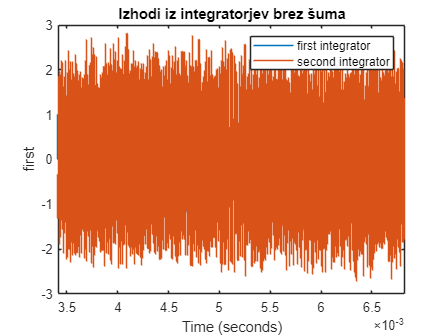

clear all;
close all;
clc;

a1 = 1;
a2 = 1;
b1 = 1;
b2 = 1;

Fs = 2.5e6;


% signal
f = 293;
AAA = 100e-3;


noise_pow1 = 1e-12;
noise_pow2 = 1e-8;

Vref = 1;

sim('SDM.slx');

% izris izhodnih signalov
% signal brez šuma
figure()
plot(first1)
hold on
plot(out_sec1)
xlim([1/f, 2/f])
legend('first integrator', 'second integrator')
title('Izhodi iz integratorjev brez šuma')

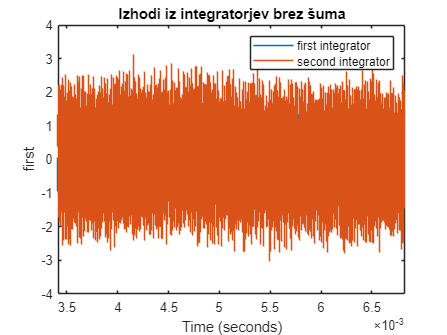

% z upoštevanim šumom
figure()
plot(first)
hold on
plot(out_sec)
xlim([1/f, 2/f])
legend('first integrator', 'second integrator')
title('Izhodi iz integratorjev brez šuma')

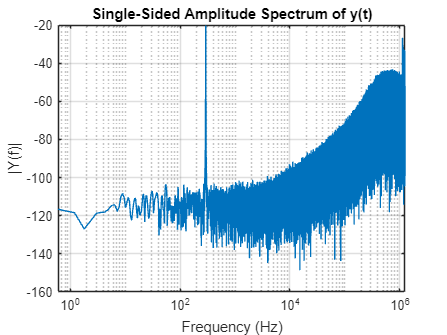

% Izris spektra z upoštevanim šumom
fft_plot(second.Data, Fs, 'log', 'dB', @blackman);

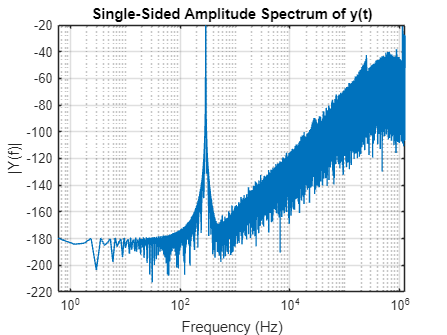

% izris spektra brez šuma
fft_plot(second1.Data, Fs, 'log', 'dB', @blackman);

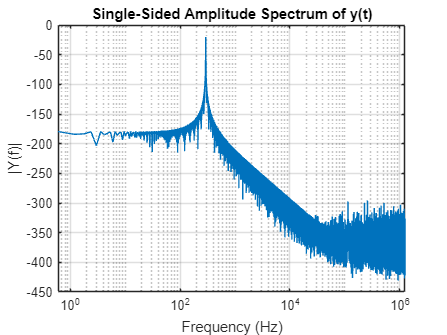


fft_plot(source.Data, Fs, 'log', 'dB', @blackman);

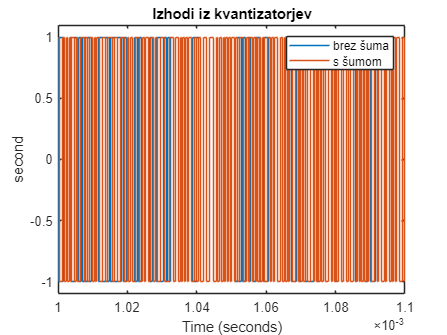


% dodaten izris izhoda iz kvantizatorja
figure()
plot(second1)
hold on
plot(second)
xlim([1e-3, 1.1e-3])
legend('brez šuma', 's šumom')
title('Izhodi iz kvantizatorjev')
xlim([1e-3, 1.1e-3])
ylim([-1.1 1.1])

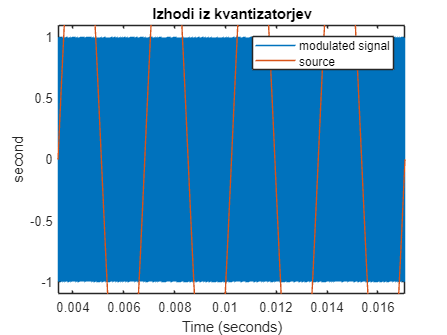

% dodaten izris primerjave izhoda iz kvantizatorja
figure()
plot(second1)
hold on
plot(source1.*25)
xlim([1/f, 2/f])
legend('modulated signal', 'source')
title('Izhodi iz kvantizatorjev')
xlim([1/f, 5/f])
ylim([-1.1 1.1])

CIC filter stage

PDM_signal = second;
NN = 8;
D = 2;
filtered = sim('CIC.slx');
fft_plot(source.Data, Fs, 'log', 'dB', @blackman);

fft_plot(PDM_signal.Data, Fs, 'log', 'dB', @blackman);

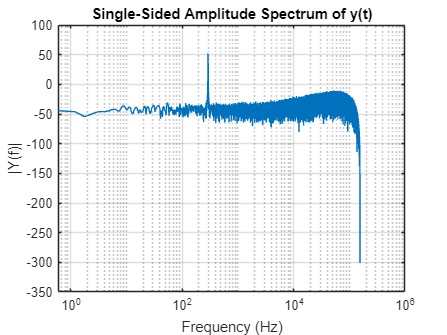

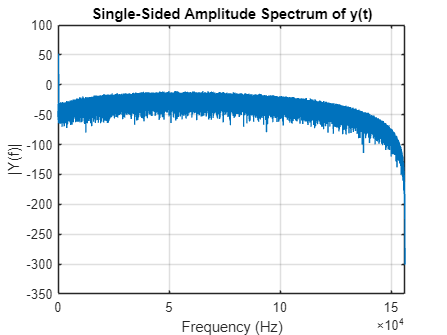

fft_plot(filtered.CIC_output_made.Data, Fs/NN, 'log', 'dB', @blackman);

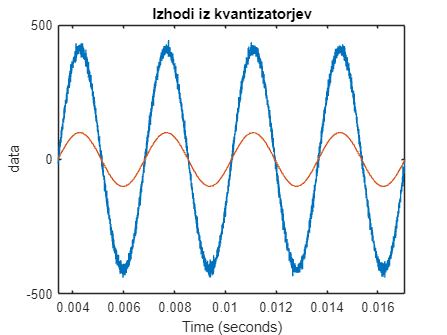

figure()
plot(filtered.CIC_output_made)
hold on
plot(source*1000)
xlim([1/f, 5/f])
title('Izhodi iz kvantizatorjev')

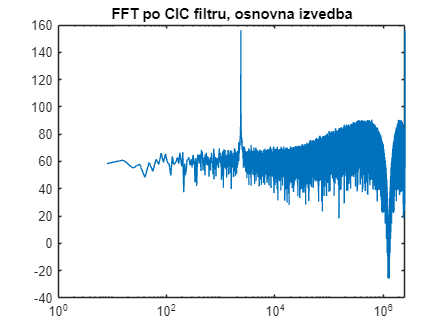

fft_d = fft(filtered.CIC_output_made.Data);
fft_d_abs = db(abs(fft_d));
tmp = Fs/length(fft_d_abs)*(1:length(fft_d_abs));
figure()
semilogx(tmp, fft_d_abs)
title("FFT po CIC filtru, osnovna izvedba")

Halfband filter stage 1

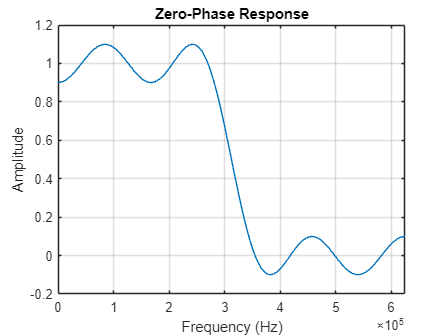

CIC_out_signal = filtered.CIC_output_made;
Fp1  = 88e3; % Passband edge
Fh1  = Fs/NN/2; % Halfband frequency
TW1 = (Fh1-Fp1)/Fh1; % Normalized transition width
N1   = 10; % Filter order
N12   = 14; % Filter order
AA1 = designHalfbandFIR(FilterOrder=N12,TransitionWidth=TW1,Passband="lowpass",DesignMethod="equiripple");
A1 = designHalfbandFIR(FilterOrder=N1,TransitionWidth=TW1,Passband="lowpass",DesignMethod="equiripple");
zerophase(AA1,1,linspace(0,Fs/4,512),Fs/2);

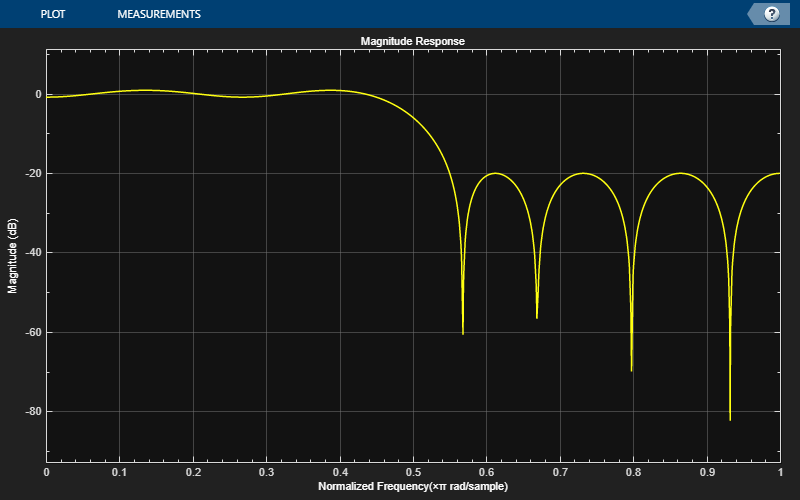

hbFIR = dsp.FIRFilter(AA1);
dfv = dsp.DynamicFilterVisualizer(NormalizedFrequency=true);
dfv(hbFIR);

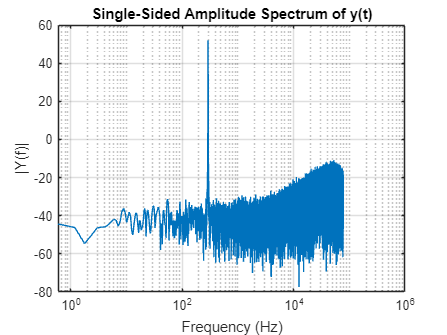

FIR_out_1 = sim('HNDF.slx');
fft_plot(FIR_out_1.discrete.Data, Fs/NN/2, 'log', 'dB', @blackman);

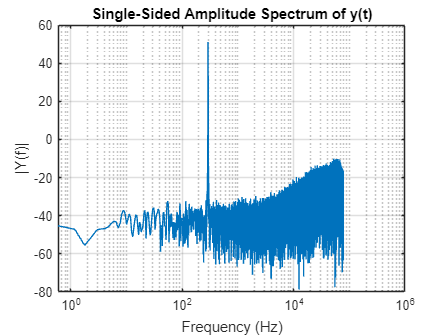

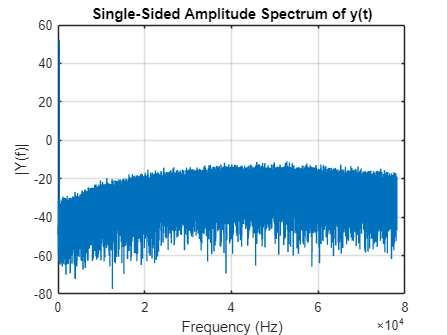

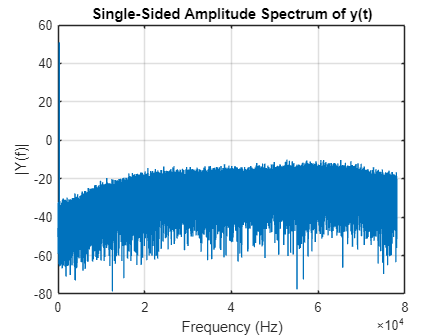

fft_plot(FIR_out_1.component.Data, Fs/NN/2, 'log', 'dB', @blackman);

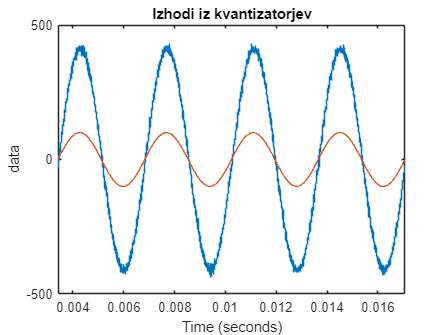

figure()
plot(FIR_out_1.discrete)
hold on
plot(source*1000)
xlim([1/f, 5/f])
title('Izhodi iz kvantizatorjev')

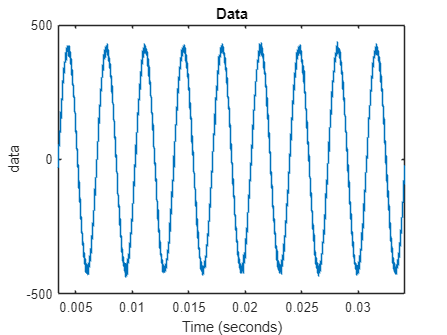

figure()
plot(FIR_out_1.discrete)
title("Data")
xlim([1/f, 10/f])

Halfband filter stage 2

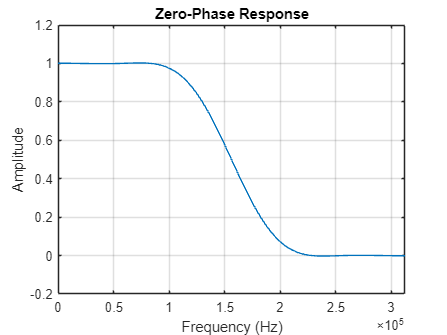

HNDF_out_signal = FIR_out_1.discrete;
Fp2  = 44e3; % Passband edge
Fh2  = Fs/NN/4; % Halfband frequency
TW2 = (Fh2-Fp2)/Fh2; % Normalized transition width
N2   = 10; % Filter order
N22   = 14; % Filter order
AA2 = designHalfbandFIR(FilterOrder=N22,TransitionWidth=TW2,Passband="lowpass",DesignMethod="kaiser");
A2 = designHalfbandFIR(FilterOrder=N2,TransitionWidth=TW2,Passband="lowpass",DesignMethod="kaiser");
zerophase(AA2,1,linspace(0,Fs/8,512),Fs/4);

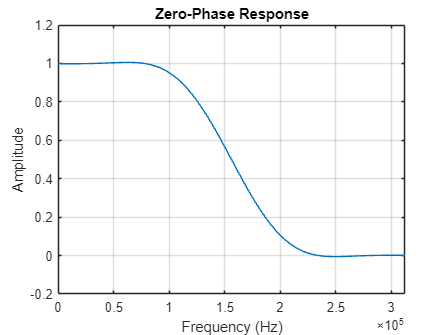

zerophase(A2,1,linspace(0,Fs/8,512),Fs/4);

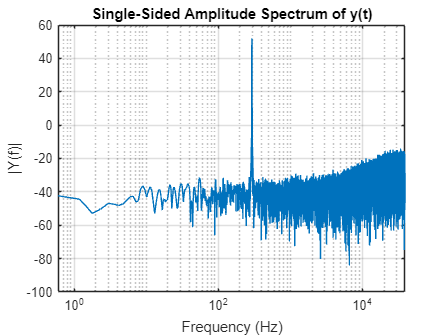

FIR_out_2 = sim('HNDF2.slx');
fft_plot(FIR_out_2.discrete.Data, Fs/NN/4, 'log', 'dB', @blackman);

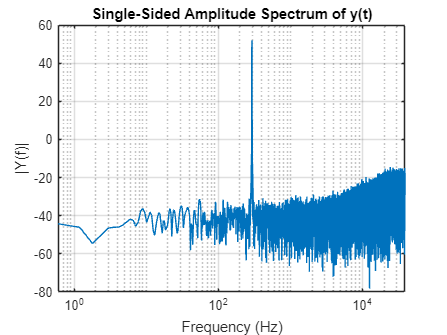

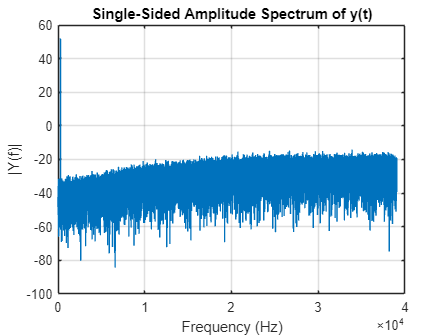

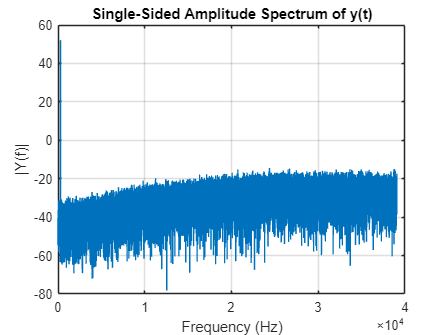

fft_plot(FIR_out_2.component.Data, Fs/NN/4, 'log', 'dB', @blackman);

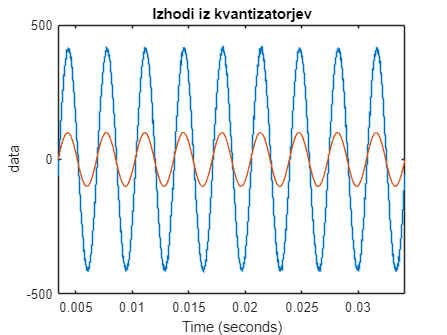

figure()
plot(FIR_out_2.discrete)
hold on
plot(source*1000)
xlim([1/f, 10/f])
title('Izhodi iz kvantizatorjev')

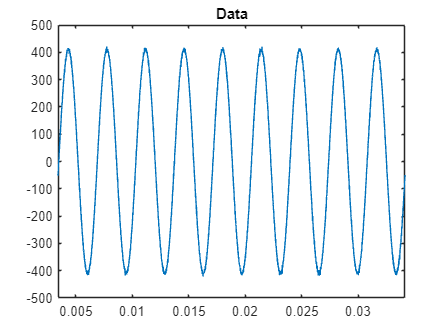

FIR_out_2_smooth = interp1(FIR_out_2.discrete.Time, FIR_out_2.discrete.Data, source.Time, 'cubic');
figure()
plot(source.Time, FIR_out_2_smooth)
title("Data")
xlim([1/f, 10/f])

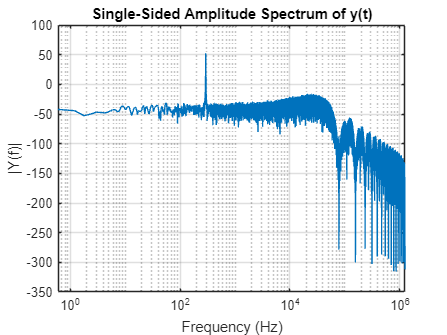

y = FIR_out_2.discrete.Data;
fft_plot(FIR_out_2_smooth, Fs, 'log', 'dB', @blackman);

Convert to VHDL test file data

PrepData = second1.Data;
PrepData = changem(PrepData, 0, -1);
PrepTable = table(PrepData);
file_Name = "TestData.txt";
writetable(PrepTable, file_Name);

Import CIC filter data for fft testing

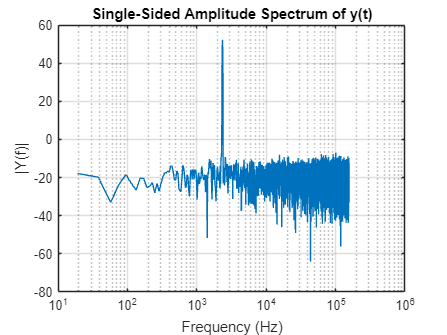

CIC_data_test = importdata("CIC_fitered_data.txt");
fft_plot(CIC_data_test, Fs/NN, 'log', 'dB', @blackman);

Prepare data for halfband filter

F_len = 5;
FUL_len = 16;
fixed_point_data1 = sfi(AA1, FUL_len+F_len, F_len);
bin_fixed_point_data1 = bin(fixed_point_data1)

bin_fixed_point_data1 = '111111111111111111110   000000000000000000000   000000000000000000010   000000000000000000000   111111111111111111101   000000000000000000000   000000000000000001010   000000000000000010000   000000000000000001010   000000000000000000000   111111111111111111101   000000000000000000000   000000000000000000010   000000000000000000000   111111111111111111110'

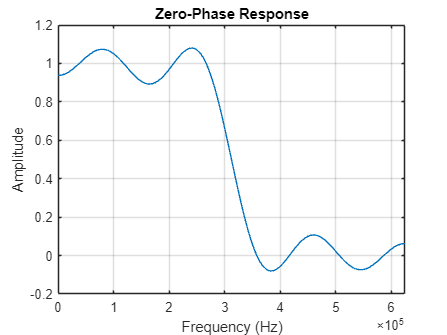

zerophase(double(fixed_point_data1),1,linspace(0,Fs/4,512),Fs/2);

Import HB1 data for fft testing

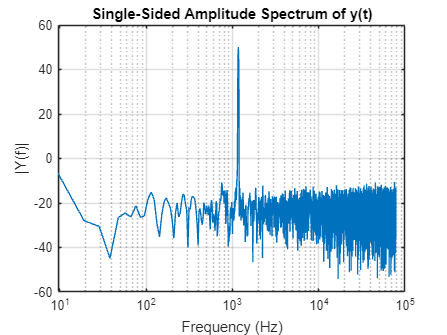

HB1_data_test = importdata("HB1_fitered_data.txt");
fft_plot(HB1_data_test, Fs/NN/2, 'log', 'dB', @blackman);

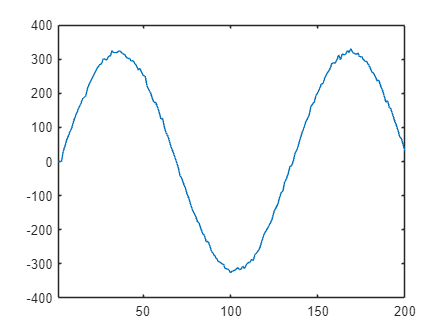

tim = 1:length(HB1_data_test);
figure()
plot(tim, HB1_data_test)
xlim([1 200])

Prepare data for halfband filter

F_len = 5;
FUL_len = 10;
fixed_point_data2 = sfi(AA1, FUL_len+F_len, F_len);
bin_fixed_point_data2 = bin(fixed_point_data2)

bin_fixed_point_data2 = '111111111111110   000000000000000   000000000000010   000000000000000   111111111111101   000000000000000   000000000001010   000000000010000   000000000001010   000000000000000   111111111111101   000000000000000   000000000000010   000000000000000   111111111111110'

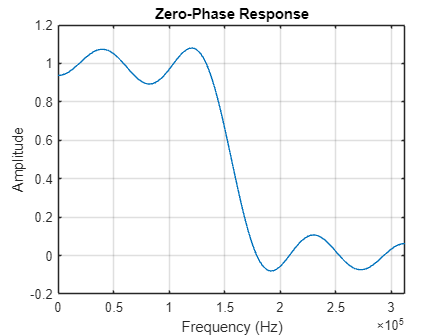

zerophase(double(fixed_point_data2),1,linspace(0,Fs/8,512),Fs/4);

Import HB2 data for fft testing

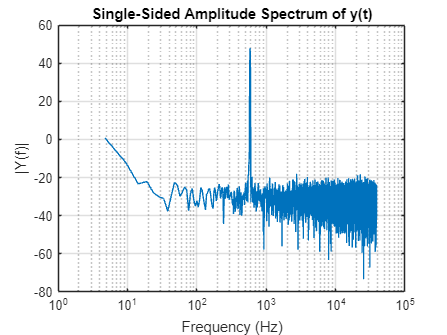

HB2_data_test = importdata("HB2_fitered_data.txt");
fft_plot(HB2_data_test, Fs/NN/2/2, 'log', 'dB', @blackman);

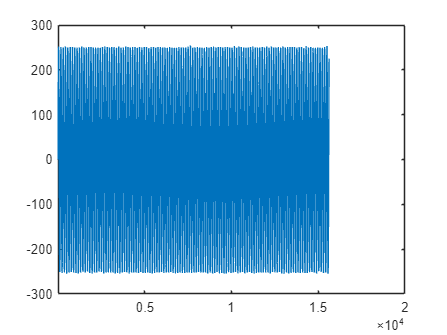

tim = 1:length(HB2_data_test);
figure()
plot(tim, HB2_data_test)
xlim([1 20000])

Full stage testing

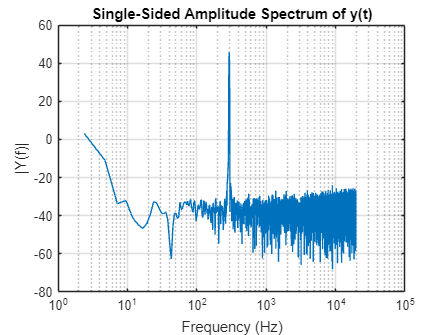

FULL_stage_data_test = importdata("FULL_stage_fitered_data.txt");
fft_plot(FULL_stage_data_test, Fs/NN/2/2/2, 'log', 'dB', @blackman);

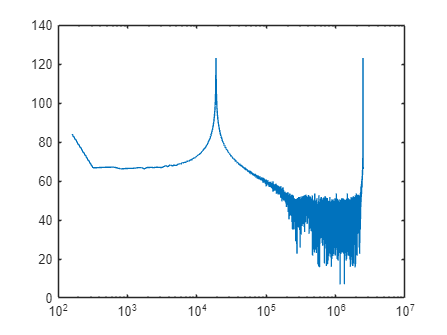

fft_f = fft(FULL_stage_data_test);
fft_f_abs = db(abs(fft_f));
tmp = Fs/length(fft_f_abs)*(1:length(fft_f_abs));
figure()
semilogx(tmp, fft_f_abs)

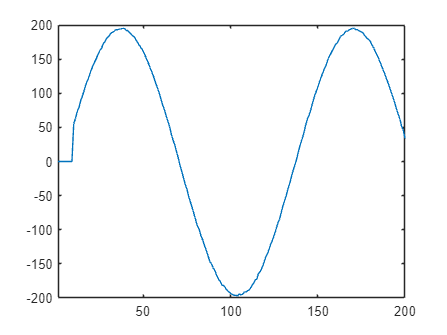

tim = 1:length(FULL_stage_data_test);
figure()
plot(tim, FULL_stage_data_test)
xlim([1 200])

PWM test

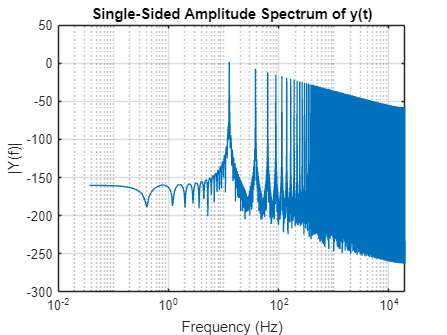

PWM_converted_data_test = importdata("PWM_converted_data.txt");
PWM_converted_data_test(PWM_converted_data_test==-1) = 1;
PWM_converted_data_test(PWM_converted_data_test==0) = -1;
fft_plot(PWM_converted_data_test, Fs/NN/2/2/2, 'log', 'dB', @blackman);

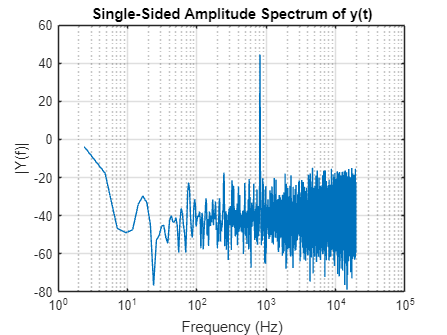

PWM_converted_data_test2 = importdata("PWM_converted_data2.txt");
fft_plot(PWM_converted_data_test2, Fs/NN/2/2/2, 'log', 'dB', @blackman);

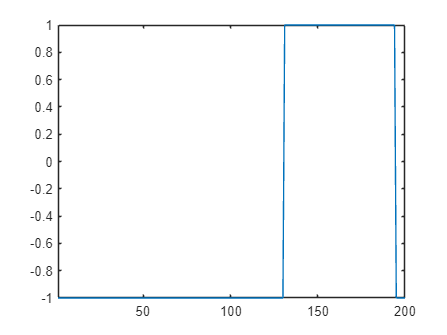

tim = 1:length(PWM_converted_data_test);
figure()
plot(tim, PWM_converted_data_test)
xlim([1 200])

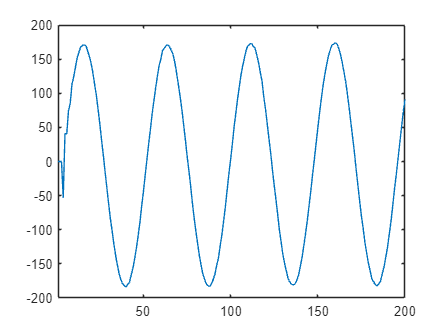

tim = 1:length(PWM_converted_data_test2);
figure()
plot(tim, PWM_converted_data_test2)
xlim([1 200])

vrednosti gausovega stožca

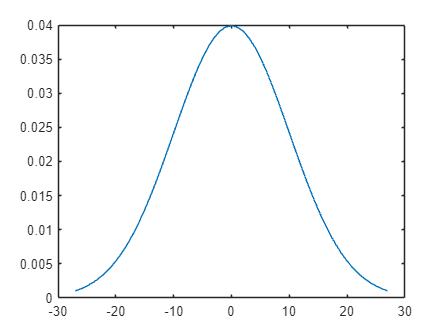

x = [-27:1:27];
y = normpdf(x,0,10);
plot(x,y)

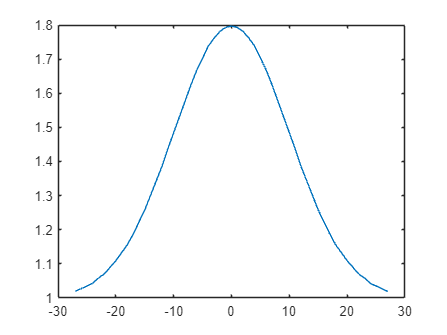

y_fixed = sfi(y*20+1, 16+16+8, 8);
plot(x,y_fixed)

y_hex = '0000000105   0000000107   0000000109   000000010b   000000010f   0000000112   0000000117   000000011c   0000000122   0000000128   0000000130   0000000139   0000000142   000000014d   0000000158   0000000163   0000000170   000000017c   0000000188   0000000194   00000001a0   00000001ab   00000001b4   00000001bd   00000001c3   00000001c8   00000001cb   00000001cc   00000001cb   00000001c8   00000001c3   00000001bd   00000001b4   00000001ab   00000001a0   0000000194   0000000188   000000017c   0000000170   0000000163   0000000158   000000014d   0000000142   0000000139   0000000130   0000000128   0000000122   000000011c   0000000117   0000000112   000000010f   000000010b   0000000109   0000000107   0000000105'

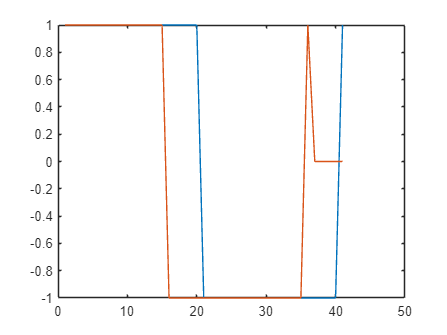

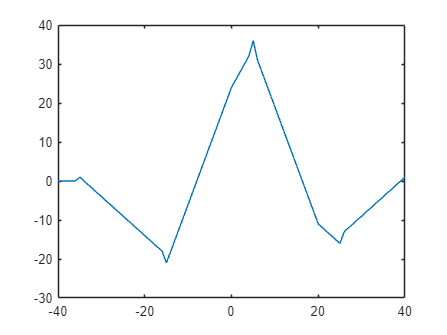

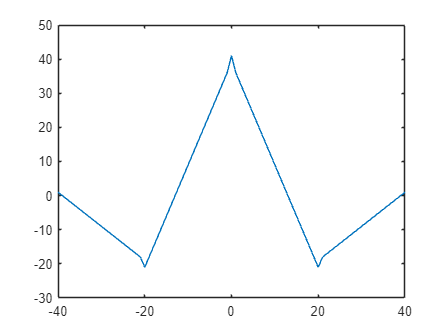

del = 5

ddel = -5

p = 40

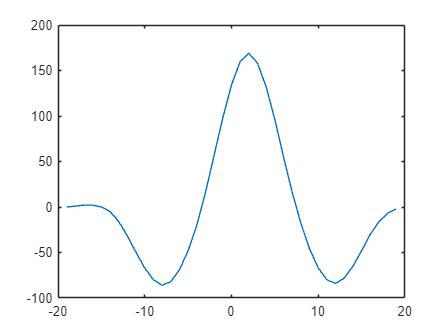

y_hex = hex(y_fixed)

beamforming coefficients

resx = 80;
resy = 60;
planex = 400;
planey = 300;
dx = planex/resx;
dy = planey/resy;
centrex = 200;
centrey = 150;
offset = 56/2;
vertical = 100;

s1 = [(centrex+offset) centrey]

s1 =    256   150


s2 = [centrex (centrey-offset)]

s2 =    200    94


s3 = [centrex (centrey+offset)]

s3 =    200   206


s4 = [(centrex-offset) centrey]

s4 =    144   150



coorx = 0:dx:planex-dx;
coory = 0:dy:planey-dy;

dis1 = zeros(resx, resy);
dis2 = zeros(resx, resy);
dis3 = zeros(resx, resy);
dis4 = zeros(resx, resy);

for x = 1:resx
    for y = 1:resy
        dis1(x,y) = sqrt((coorx(x)-s1(1))^2 + (coory(y)-(s1(2)))^2 + (vertical)^2);
        dis2(x,y) = sqrt((coorx(x)-s2(1))^2 + (coory(y)-(s2(2)))^2 + (vertical)^2);
        dis3(x,y) = sqrt((coorx(x)-s3(1))^2 + (coory(y)-(s3(2)))^2 + (vertical)^2);
        dis4(x,y) = sqrt((coorx(x)-s4(1))^2 + (coory(y)-(s4(2)))^2 + (vertical)^2);
    end
end

dis1 = dis1./1000;
dis2 = dis2./1000;
dis3 = dis3./1000;
dis4 = dis4./1000;

fs = 3.072e6/64;
c = 330;
a = 1;
coef = a*fs/c;

del1 = coef.*dis1;
del2 = coef.*dis2;
del3 = coef.*dis3;
del4 = coef.*dis4;

delta1 = round(del1);
delta2 = round(del2);
delta3 = round(del3);
delta4 = round(del4);

delta1 = delta1 - min(min(delta1));
delta2 = delta2 - min(min(delta2));
delta3 = delta3 - min(min(delta3));
delta4 = delta4 - min(min(delta4));

writematrix(delta1,'delta1.csv')
writematrix(delta2,'delta2.csv') 
writematrix(delta3,'delta3.csv') 
writematrix(delta4,'delta4.csv') 
